# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

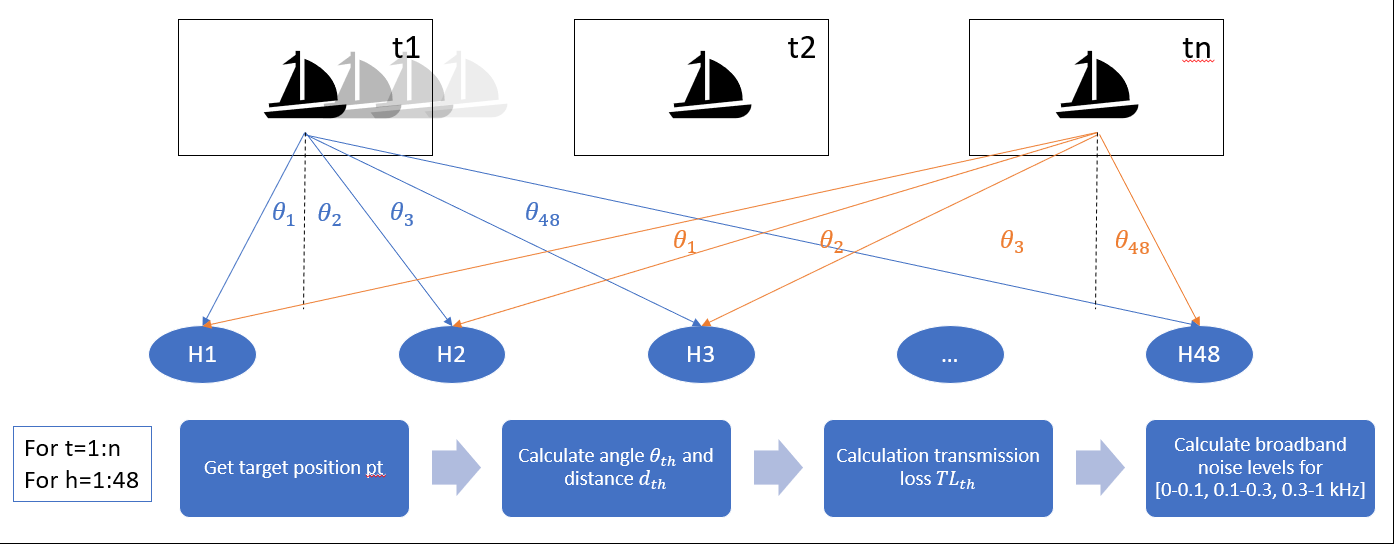

## Initialize & set parameters

clearvars
load arrays_lat-long
array1=table2array(array1(:,1:2));
array2=table2array(array2(:,1:2));

Num1secSeg = 5;                             %number of segments for averaging
TimeIntSec = 3;                             %time-difference [sec] btw. beginning of segments
fstartind = 10;                             %10Hz for computing received levels
fstopind = 1001;                            %1000Hz for computing received levels
NumRec = 2; %48;                                %Number of recorder channels
BinWidth = 1;                               %Bin Width [Hz] 

## Acoustic data pre-processing

### Define parameters

sens = 194.5;  % (nominal) dB re 1V/uPa
cal = 10^(sens/20); 
%gain = 70;   % Amplifier gain 70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)
adc = 5/(2^16); % 1 Vrms = 16 bit peak-to-peak --> could also be +/- 1 floating point range (20log(2.0/5.0))

### Load acoustic data

dFile = 'allCh.wav';           % Select the 48-ch (allCh) or 1-ch (singleCh) file
%NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\HebSky\proc',dFile);
NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\proc',dFile);
%NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\west_aaa2_20150830_094520_00_0010.wav');
[x,fs] = audioread(NWFile);  % What is this signal? Volts? --> need to convert to dB (x/sens)
SegLengthSamples = BinWidth*fs; 
DataLengthSamples = Num1secSeg*SegLengthSamples;
%x = x/cal;

### Downsample acoustic data (optional)

sampling = 'full'; %'downsample'; % or 'full'

switch sampling
    case 'full' 
        nFactor = 1;
        disp('sampling full band')
    case 'downsample'
        nFactor = 1000;
        y = downsample(x,nFactor); %downsample or decimate?
        x = y; 
        clear y
end

sampling full band


[nsam,nch] = size(x);

### Generate time vector

%t = cumsum(ones(length(x(:,1))/fs,1)); % time vector in seconds
%t = seconds(t*nFactor);
% %startTime = datetime(2015,8,26,16,59,58);  % HebSky - west_aaa2_20150826_165958_00_0131
startTime = datetime(2015,8,30,9,17,24);  % OcEnd - west_aaa2_20150830_091724_00_0007
StartTime = datenum(startTime);
endTime = startTime + seconds(length(x(:,1))/fs);  % length(x)/fs = 
EndTime = datenum(endTime);
TimeVector = StartTime:TimeIntSec/(3600*24):EndTime;
%t = t + startTime;
%TimeVector = datenum(t);
%StartTime = datenum(startTime);
%EndTime = datenum('08/30/2015 09:17:24');
%TimeVector = StartTime:TimeIntSec/(3600*24):EndTime;    %1x601
NumSpec = length(TimeVector);                           %601

### Transfer function for array

One-sided to save memory

fRspectra = fs/2*linspace(0,1,SegLengthSamples/2+1); %frequencies [Hz]
% G = 10^(sens/20)*ones(length(fRspectra),1);
G = 10^(sens/20);

## Received Spectra with 1 Hz bins

Paper: Each of the eight pressure time series was divided into consecutive, non-overlapping segments with a length of 1 s (200 000 samples).

S =  cell(NumRec,1);   % Spectra for each array elements
for RecInd=1:NumRec
    S{RecInd} = zeros(NumSpec-2,SegLengthSamples/2+1);  % 48 x fs  (one-sided)
end

### Loop to read data piece by piece

for EventIndex = 1:(NumSpec-2)
    for RecInd=1:NumRec   
        data = x(TimeIntSec*fs*(EventIndex-1)+1:...
         TimeIntSec*fs*(EventIndex-1)+DataLengthSamples,RecInd);
        NumSeg = floor(length(data)/SegLengthSamples);
        %FileIndex = ...
            %find((xwavReferenceTime{RecInd}(:) - TimeVector(EventIndex))<0);
            %%need to find a way to handle partial segments
%         StartSample = round(fs*(TimeVector(EventIndex) - ...
%                     StartTime)*(24*3600)); 
%         data = MTRead(filename{RecInd}{FileIndex(end)},...
%                     StartSample,StartSample+DataLengthSamples(RecInd)-1,'p');    
         %data=data.';

### Compute received spectra

Paper: A two-sided Fast Fourier Transform (FFT) with NFFT=200 000 points was applied to each segment to yield a frequency bin spacing of 1 Hz. The magnitude squared values of the complex FFT coefficients for the positive frequencies were multiplied by 2/NFFT^2 to account for the processing gain of the FFT.

Compute onesided spectra and calibrate with HARP specific hydrophone transfer functions

%         for SegInd=1:NumSeg  
%             X = fft(data(:,SegInd));
%             S{RecInd}(EventIndex,:) = S{RecInd}(EventIndex,:) + ...
%                         (((2*abs(X(1:SegLengthSamples/2+1,:)).^2)*G^2)...
%                         /(SegLengthSamples*fs)).';         
%         end
    
    X = fft(reshape(data(1:NumSeg*SegLengthSamples),...
                SegLengthSamples,NumSeg));
            %compute onesided spectra and calibrate with HARP specific hydrophone transfer functions
            S{RecInd}(EventIndex,:) = ...
                (sum(2*abs(X(1:SegLengthSamples/2+1,:)).^2,2)*G^2)...
                /(NumSeg*SegLengthSamples*fs);        
    end
        
    %display progress
    if mod(EventIndex,round(NumSpec/10))==0
        disp([num2str(round(100*EventIndex/NumSpec)) '% done'])   
    end
end

10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done


gain = -78;   % Amplifier gain -70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)

### Plot Spectrograms

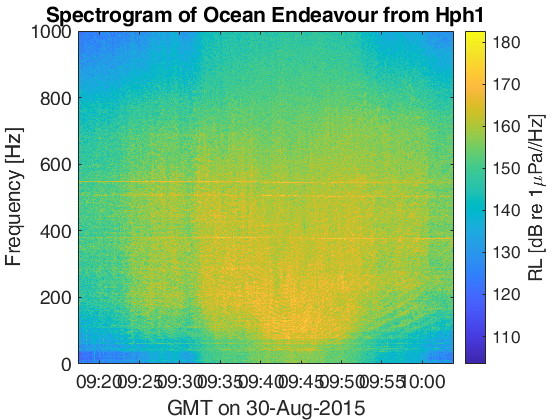

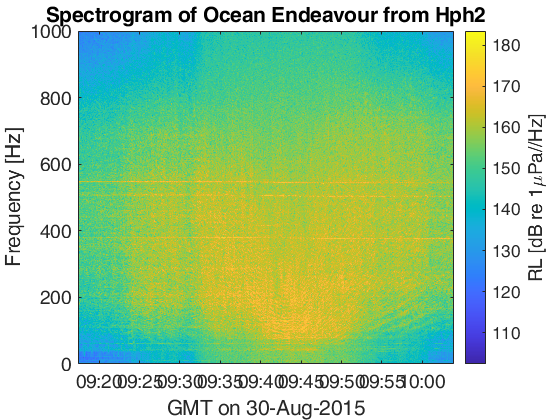

FontSizeNumber=14;
for RecInd=1:NumRec
figure;
    %RecInd = RefRecInd;    
    imagesc(TimeVector,fRspectra,10*log10(S{RecInd}).');
    title(['Spectrogram of Ocean Endeavour from Hph' num2str(RecInd)],'FontSize',FontSizeNumber)
    axis xy; 
    h = colorbar;%caxis([50 130])
    set(get(h,'ylabel'),'string','RL [dB re 1\muPa//Hz]',...
        'FontSize',FontSizeNumber);
    datetick('x','keeplimits');
    xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')],...
        'FontSize',FontSizeNumber)
    ylabel('Frequency [Hz]','FontSize',FontSizeNumber)
    ylim([0 1000])
    set(gca, 'FontSize',FontSizeNumber)
end

## Plot Average Spectra

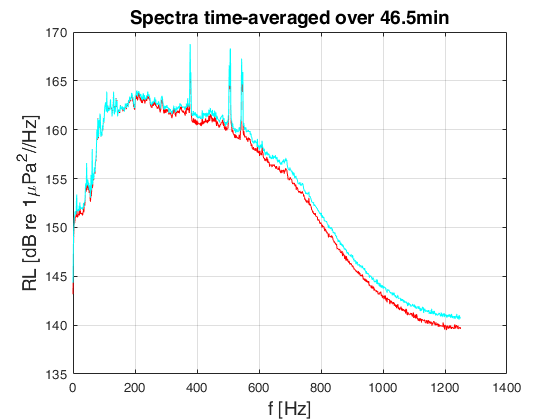

figure; 
NumLinesPlot = 2;
NumSubPlots = ceil(NumRec/NumLinesPlot);
colorarray = hsv(NumRec);
for RecInd=1:NumRec
    SubPlotInd = floor(RecInd/(NumLinesPlot+1))+1;
    if RecInd == 7 
        SubPlotInd = 3; 
    end
    subplot(NumSubPlots,1,SubPlotInd)
        plot(fRspectra,10*log10(sum(S{RecInd})/NumSpec),...
            'Color',colorarray(RecInd,:));
        hold on
        %ylim([60 130])
        %xlim([5 100])
        grid on        
        if SubPlotInd == 1
            title(['Spectra time-averaged over '...
                num2str((TimeVector(end)-TimeVector(1))*24*60) 'min'],'FontSize',FontSizeNumber)
        end            
        ylabel('RL [dB re 1\muPa^2//Hz]','FontSize',FontSizeNumber)
        xlabel('f [Hz]','FontSize',FontSizeNumber)
end

## Compute received levels

RLship = zeros(NumRec,NumSpec-2);       %broad band received level [dB]

for RecInd = 1:NumRec    
    for index=1:NumSpec-2  
        %compute source level from spectrum for beam angle           
        RLship(RecInd,index) = 10*log10(trapz(fRspectra(fstartind:fstopind),...
            (S{RecInd}(index,fstartind:fstopind))));%...
    end
end
RLship = RLship';

## Spatial data processing

### Load AIS file

Load - sync to spec - calc TL - calc SL - 

m = matfile('byShip.mat');
AIS = m.Oc_End; %m.Heb_Sky;
AIS = sortrows(AIS,'datetime','ascend');
mmsi = AIS.mmsi(1); 
AIS.mmsi = []; AIS.rate_of_turn = []; AIS.hdg = [];  % eliminate unused vars
AIStime = table2timetable(AIS);  % might need to make all of this a structure
AIStimeRange = timerange((startTime),(endTime-seconds(6)));  %because integration periods 
AIStime = AIStime(AIStimeRange,:);

%NumAISlocs = length(AIS.time);

%map AIS lats/longs to x-y    
% [AIS.x, AIS.y] = latlon2xy(AIS.lat,AIS.long,...
%         CINMS_B_30(RefRecInd).lat,CINMS_B_30(RefRecInd).long);


### Synchronize spectral and spatial data

Make RL and TL same length and combine in time 

timeVector = datetime(TimeVector(1:length(S{1}(:,1))),'ConvertFrom','datenum')';
RLtime = timetable(timeVector,RLship);
SPL = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(3)); %'KeepOriginalTimes',true
SPL = SPL(1:height(RLtime),:); %[RLsync,AISsync] = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));


### Calculate ranges along ship track

[R1,R2] = calcDist(SPL.lat, SPL.long, array1, array2);
SPL = addvars(SPL,R1,R2);

### Calculate CPA range and time

[rangeCPA_1,timeCPA_1] = min(R1(:,1,1));
[rangeCPA_2,timeCPA_2] = min(R2(:,1,1));
specCPA = 'CPA range AAA1 = %4.2f km and AAA2 = %4.2f km';
fprintf(specCPA,rangeCPA_1,rangeCPA_2); 

CPA range AAA1 = 2.04 km and AAA2 = 1.33 km

### Plot bearing histogram of ranges

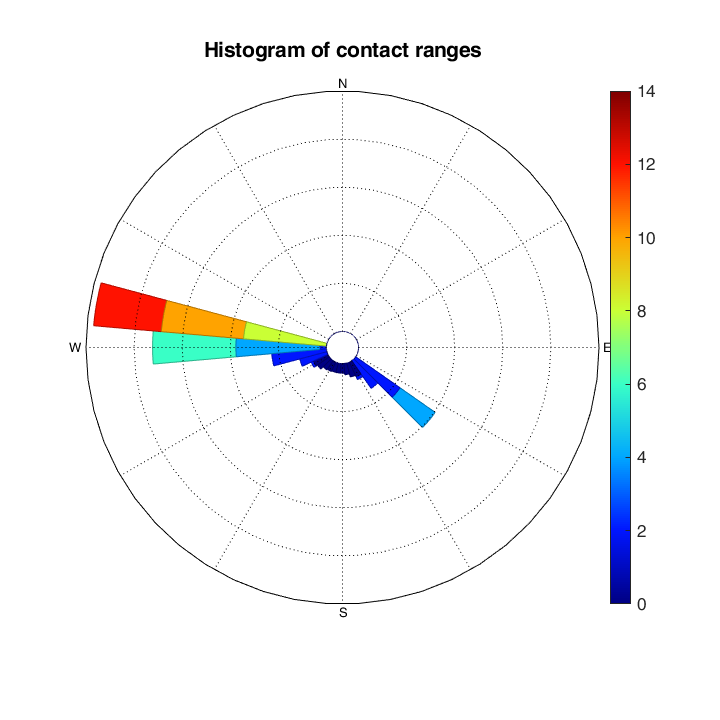

rangeRoser(R2(:,1,2), R2(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
set(gca,'FontSize',14);

### Plot time resolution of AIS data, speed and range history of contact

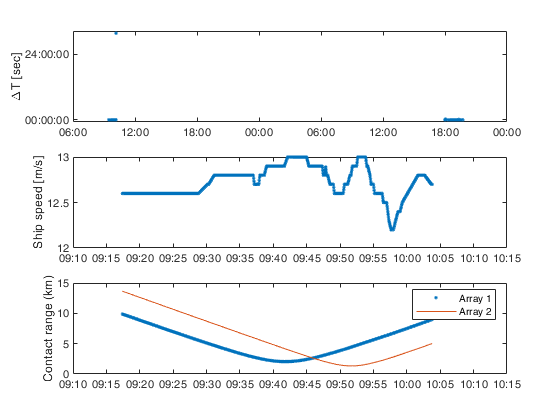

figure
subplot(3,1,1)
    plot(AIS.datetime(1:end-1),diff(AIS.datetime),'.');
    datetick('x')
    ylabel('\DeltaT [sec]')    
subplot(3,1,2)
    plot(SPL.timeVector,SPL.speed_over_ground,'.');
    datetick('x')
    ylabel('Ship speed [m/s]') 
subplot(3,1,3)
    plot(SPL.timeVector,R1(:,1,1),'.');
    hold on
    plot(SPL.timeVector,R2(:,1,1),'-')
    datetick('x')
    ylabel('Contact range (km)')  
    legend('Array 1','Array 2')

## Compute radiation pattern

SL.broadband = zeros(NumRec,NumSpec-2); %broadband source level [dB]
SL.ALL = cell(NumRec,1);                %source spectra level [dB]

for RecInd = 1:NumRec    
    SL.ALL{RecInd} = zeros(NumSpec-2,SegLengthSamples/2+1);
    for index=1:NumSpec-2  
        %compute source level from spectrum for beam angle           
        SL.broadband(RecInd,index) = ...
            SPL.RLship(index,RecInd) + 20*log10(SPL.R2(index,RecInd,1));   %SL = RL + TL
        SL.ALL{RecInd}(index,:) = ...
            10*log10(S{RecInd}(index,:))+20*log10(SPL.R2(index,RecInd,1));   % SL =      
    end
end

## Calculate lobing pattern

#### Determine look angle (aspect)

SPL.aspect2 = SPL.crs - SPL.R2(:,:,2);

Unrecognized table variable name 'hdg'.

SPL.rads2 = deg2rad(SPL.aspect2);

### Plot lobing pattern

figure
polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
figure
polarscatter(SPL.rads2(:,1)',SL.broadband(1,:))
rlim([180 210])
title('Radiated broadband noise pattern (dB)')
hold on 
polarscatter(SPL.rads2(:,2)',SL.broadband(2,:))

## Junk

### Plot signal and SPL

figure
subplot(3,1,1)
    plot(t,x(1))
    axis tight
    ylabel('pressure (Pa)')
subplot(3,1,2)
    plot(t,RL2(1))
    axis tight
    ylabel('spl (dB)')
subplot(3,1,3)
    plot(AIS.datetime,R2(:,1,1),'.');
    datetick('x')
    ylabel('Contact range (km)')   

### Loop through array elements

fileName = 'ArraySPLWindows.mat';
matObj = matfile(fileName);
matObj.Properties.Writable = true;
matObj.RL1 = zeros(nsam,nch); matObj.RL2 = zeros(nsam,nch);
for ich = 1:nch   
    fprintf('Writing %d of %d\n',ich,nch);
    RL2 = gain + spl(x(:,ich),'water',windowSize,fs);     % calculate SPL using spl sub-routine with 1-sec windows re 1uPa
    matObj.RL2(:,ich) = RL2;
end

%RL = table(RL1,RL2);
%RLtime = array2timetable(RL,'RowTimes',t);   %could shorten this 


### Plot lobing pattern

figure
polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
figure
polarscatter(SPL.rads2,SPL.SL2)
title('Radiated noise pattern (dB)')

R =  cell(NumRec,1); % Range and bearing for each array element
for RecInd=1:NumRec
    R{RecInd} = zeros(NumSpec-2,2);
end

### Loop to read data piece by piece

for EventIndex = 1:(NumSpec-2)
    for RecInd=1:NumRec   
        R{RecInd}(EventIndex,:) = 0;        
    end
end